# Aula 3 - Laboratório de Controle - 2021/1 

## Identificação de modelos a partir de dados

## Nome: Arthur Lorencini Bergamaschi

**Atividade 1: Análise da resposta do motor**

O modelo do motor utiizado é mostrado na Figura 1. A entrada é o sinal PWM e a saída agora é a rotação, em RPM. Um sinal de ruído é adicionado a saída.

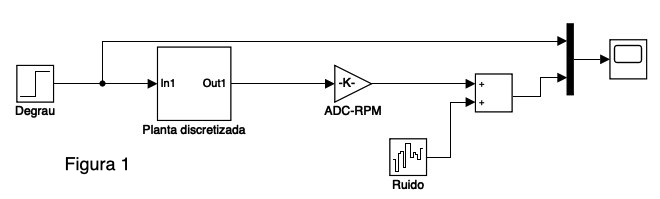

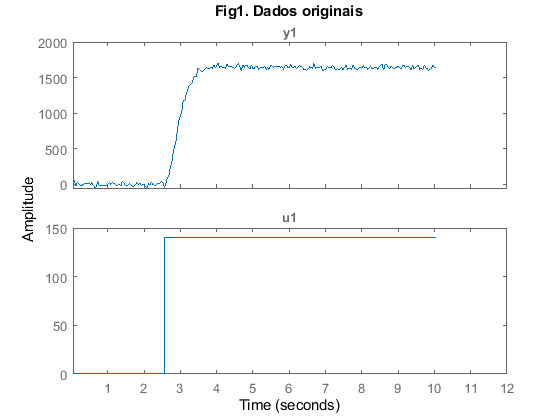

Tempo = 10;
arquivo='aula3_2018.slx';
Stepdelay=0.25*Tempo;
I = 1;
Turma = 2;

[wn,PWM,rpm_r,Ts]=init(I,Turma);
warning('off','all');
[y,u,t]=simula_slx(arquivo,Tempo);
dat=iddata(y,u,Ts);
plot(dat); title('Fig1. Dados originais')

1.1 Explicar o que representam as duas curvas da Figura 1.

A figura de baixo mostra o degrau unitário que parte depois de um delay de 2.5s. A figura acima mostra a resposta do sistema em rpm com a adição de um ruído. Veja que existe uma curva mostrando a demora que o sistema leva para chegar no seu valor de regime.

1.2 Calcular o valor da entrada PWM para ter em regime uma saída de velocidade = rpm_r. Explicar o cálculo e informar como obter o valor da saída em regime na figura 2.

O cálculo do PWM é feito achando o ganho. 1680/140 = 12. Com isso, para ter um rpm_r de 800, o PWM precisa ser 800/12 = 66.6

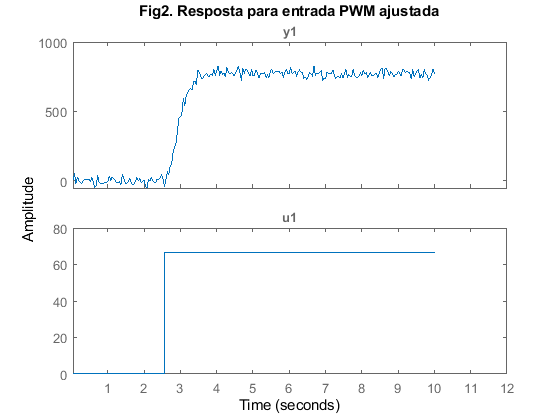

PWM=66.6;
[y,u,t]=simula_slx(arquivo,Tempo);
dat=iddata(y,u,Ts);
plot(dat);title('Fig2. Resposta para entrada PWM ajustada')

**Atividade 2: Identificação dos modelos contínuos de ordem 1 e 2**

Ler o apêndice sobre a identificação de funções de transferência e o sobre o índice fit para medir a qualidade do modelo. Depois, use os comandos abaixo para estimar a FT g1 de ordem 1 e a FT g2 de ordem 2.

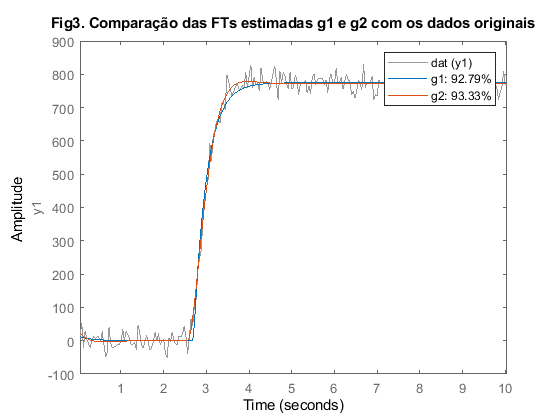

delay=t(sum(y<0.1*y(end)))-Stepdelay;
g1=tfest(dat,1,0,delay);
g2=tfest(dat,2,0); 

figure;compare(dat,g1,g2);
title('Fig3. Comparação das FTs estimadas g1 e g2 com os dados originais');

2.1 Explique o comando tfest e analise o FIT de g1 e g2, comparando.

O comando tfest serve para estimar a função de transferência e devolver um modelo que mais se adequa aos dados informados. O g2 possui um FIT (93.33%) maior do que o g1 (92.79%), mostrando que o modelo de segunda ordem, para este caso em específico, se encaixa melhor do que um modelo de primeira ordem.

2.2 Compare esse método de estimar g1 ao utilizado na aula 2 (atividade 2).

Na atividade 2, nós fizemos uma estimativa de um sistema de primeira ordem avaliando a norma euclidiana do erro de dez valores de tempo morto, a partir daí, vemos qual é o melhor tau para aproximar o modelo. Além disso, nós calculamos o ganho fazendo uma relação entre a saída e a entrada. O dessa atividade nós utilizamos o tfest utilizando os dados que nos foram fornecidos, com exceção do delay, e ele nos fornece o valores de K e de tau.

2.3 Compare g1 com a FT G de primeira ordem+tempo morto $G=\frac{e^{ds}K}{\tau s + 1}$ e obtenha o ganho $K$ e a constante de tempo $\tau$.

Por comparação, vemos que o K é 11.7361 e fazemos a divisão pelo polo e vemos que o tau é 0.3040s.

2.4  Compare g2 com o protótipo de segunda ordem em malha fechada $M(s)=\frac{w_n^2}{s^2+2\zeta w_n s + wn^2}$ e obtenha $\zeta$ e $w_n$. 

Por comparação, vemos que $w_n$ = 13.82 e $\zeta$ = 0.4878

**Atividade 3 - Aproximação de Padé do tempo morto**

A aproximação de [Padé](https://youtu.be/zDRTsU2DZSk) permite aproximar o atraso $e^{-ds}$ por polos e zeros, e assim obter FTs racionais na presença de atrasos (ver apêndice 2)

No script a seguir, usa-se aproximação de Padé de ordem 1,2,10 para aproximar o tempo morto de g1 por polinômios.

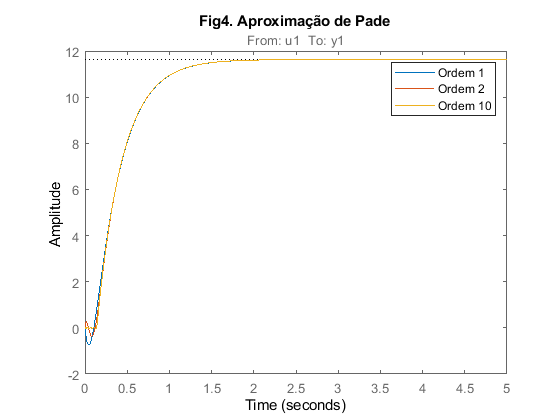

g1p=pade(g1,1);
g2p=pade(g1,2);
g10p=pade(g1,10);
figure(7);step(g1p , g2p, g10p, Tempo/2 );title('Fig4. Aproximação de Pade');legend('Ordem 1', 'Ordem 2', 'Ordem 10');

3.1 Use a aproximação de Padé para obter uma FT de malha fechada m1 de g1 e obtenha seus polos (ver links de ajuda na aula 2).

m1_1 = feedback(g1p,1);
m1_2 = feedback(g2p,1);
m1_10 = feedback(g10p,1);
fprintf("Polos de malha fechada g1p");pole(m1_1)

ans =    1.8139 + 5.7213i
   1.8139 - 5.7213i


fprintf("Polos de malha fechada g2p");pole(m1_2)

ans =  -23.6239 + 0.0000i
   1.3088 + 4.0728i
   1.3088 - 4.0728i


fprintf("Polos de malha fechada g10p");pole(m1_10)

ans = 	1.0e+02 *

  -1.5109 + 0.0000i
  -0.3117 + 0.7369i
  -0.3117 - 0.7369i
  -0.0531 + 0.4241i
  -0.0531 - 0.4241i
  -0.0247 + 0.2816i
  -0.0247 - 0.2816i
  -0.0126 + 0.1564i
  -0.0126 - 0.1564i
   0.0124 + 0.0403i


3.2 Use o comando [rlocus](https://www.mathworks.com/help/control/ref/tf.rlocus.html) para explicar o que ocorre com as raízes de 1+kg1(s)=0 (polos de malha fechada) quando o ganho k varia de zero a infinito (coloque apenas texto e informações do LR, sem comandos ou figuras).

Para rlocus(g1p), se K tende ao infinito, então ele vai deixando o sistema instável. O K é maior do que 0.48, nós vemos que o sistema fica instável. Como temos um polo sem par, temos uma assíntota no eixo real. Como só temos 2 polos e 1 zero, a análise fica mais fácil de fazer.

Para rlocus(g2p), temos 3 polos no lado esquerdo do plano S e dois zeros no outro. O sistema fica instável se K é maior que 0.381, pois os polos vão estar no lado direito do plano S. Como temos 1 polo sem par, então temos uma assintota no eixo real. Quando K vai aumentando, o polo sem par deixa o sistema mais estável, mais os outros dois tendem a deixar mais instável (porém, com 'velocidades' menores). Fazer a análise do sistema com 5 componentes ainda é humanamente possível.

Para o rlocus(g10p), temos 11 polos no lado esquerdo do plano S e 10 zeros no outro. O sistema fica instável para K maior que 0.497. Além disso, temos um polo sem par, temos uma assíntota no eixo real. Como temos 21 componentes, fica visualmente dificil de analisar o efeito ao variar o ganho no sistema, pois temos cerca de 11 caminhos para serem analisados simultaneamente, apesar de ser um modelo mais preciso que os outros dois modelos anteriores (ao observar a figura 4). 

Portanto, temos que o g2p é um modelo mais adequado para as nossas condições, pois temos um modelo satisfatoriamente preciso e não muito complexo de ser analisado.

datetime('now')

ans = datetime
   02-Jul-2021 11:04:52


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Aula3'

**Apêndice 1**

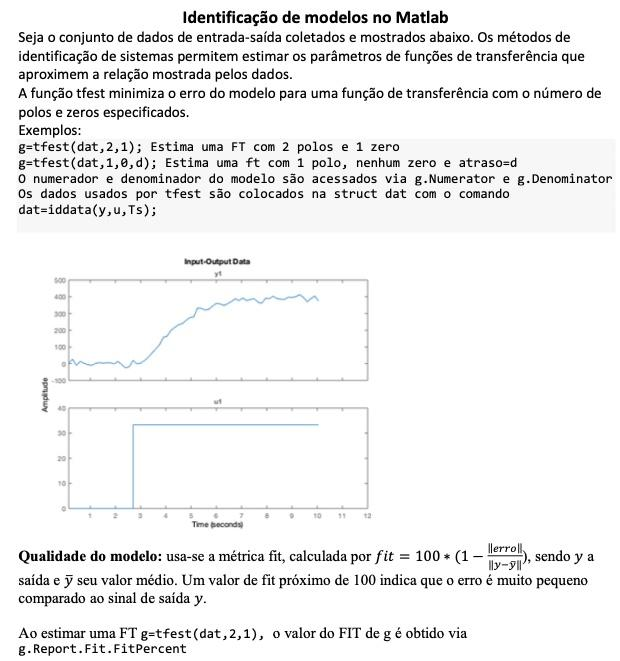

**Apêndice 2**